# Discrete SS Controller Using LQR

Cameron Wolfe 8/2/2022

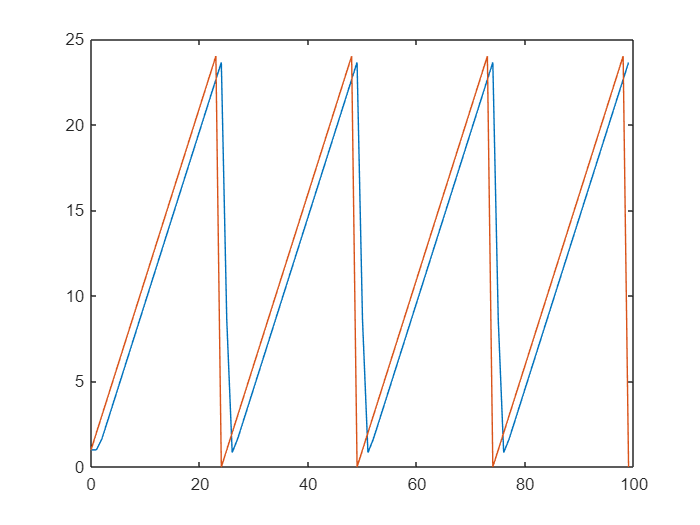

tau = .01;
Km = 1000;
deltaT = .02;
numIter = 100;
numCycles = 2;

Ac = [0 1; 0 -1/tau];
Bc = [0;Km/tau];
C = [1 0];
D = 0;

sys = ss(Ac, Bc, C, D);
dSys = c2d(sys, deltaT);
A = dSys.A;
B = dSys.B;

% Don't care about omega, so make Q for omega smaller than for position
K = -dlqr(A,B,[1 0; 0 .0001], .1);

x = zeros(2, numIter);
r = zeros(2, numIter);
r2 = zeros(2, numIter);
for i = 1:numIter 
    r(1,i) = mod(ceil(2*i*numCycles/numIter), 2);
    r(1,i) = mod(i, numIter/(2*numCycles));
end
u = zeros(1, numIter);
y = zeros(1, numIter);
x(:,1) = [1; 0];

for i=1:numIter-1
    y(i) = C * x(:,i);
    u(i) = K * (x(:,i)-r(:,i));
    x(:,i+1) = A*x(:, i) + B * u(i);
end
y(end) = C*x(:,end);

plot(0:numIter-1, y);
hold on;
plot(0:numIter-1, r(1,:));
hold off;